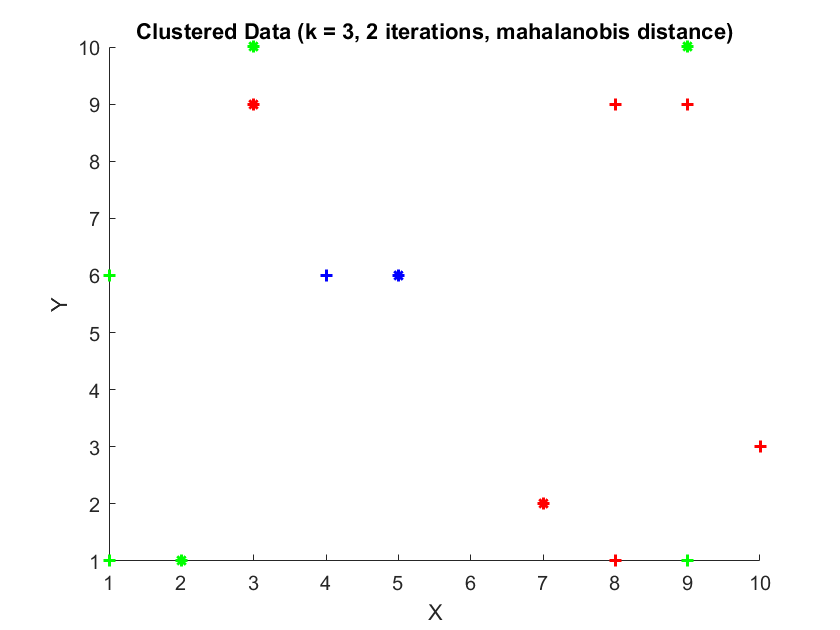

% Load data from .CSV file. note that data has be cleaned up
data = csvread('data.csv');

% Extract x,y, andlabel columns
x = data(:, 1);
y = data(:, 2);
labels = data(:, 3);

% Prompt the user for the number of clusters (k),
k = input('Enter  num of clusters: ');

% Prompt the user for the num of iterations
num_iters = input('Enter the num of iterations: ');

% Prompt the user for the distance metric to use
dist_metric = input('Enter "euclidean" or "mahalanobis" for the distance metric: ','s');

% k-means clustering
if strcmp(dist_metric, 'mahalanobis')
    % Use Mahalanobis distance
    D = mahal([x y],[x y]);
    idx = kmeans(D,k,'MaxIter',num_iters);
else
    % Use Euclidean distance
    idx = kmeans([x y],k,'Distance','sqeuclidean','MaxIter',num_iters);
end

% Plot the clustered data
figure;
hold on;
colors = hsv(k); % generate k distinct colors per cluster group
for i = 1:k
    scatter(x(idx==i & labels==1), y(idx==i & labels==1), '+', 'MarkerEdgeColor', colors(i,:), 'LineWidth', 1.5);
    scatter(x(idx==i & labels==2), y(idx==i & labels==2), '*', 'MarkerEdgeColor', colors(i,:), 'LineWidth', 1.5);
end
hold off;

% Set axis labels and graph title
xlabel('X');
ylabel('Y');
title(sprintf('Clustered Data (k = %d, %d iterations, %s distance)', k, num_iters, dist_metric));